% defines aircraft variables

Cd = 0.6        % drag coefficient

Cd = 0.6000

Cl = 0.5        % lift coefficient

Cl = 0.5000

g = 9.81        % gravity

g = 9.8100

p = 1.225       % air density

p = 1.2250


% total TOWs
m1 = 2.5

m1 = 2.5000

m2 = 3

m2 = 3

m3 = 3.5

m3 = 3.5000


% total frontal area (CAD + 0.015/arm +0.007/LG)
Af = 0.032   

Af = 0.0320

At = 0.071

At = 0.0710


lmm = 0.032;
hmm = 0.152;
mmAdj = 4*(hmm-lmm);

% motor thrust models
m0m = 0.5743;
m2m = 0.1649;
m0c = -175.5;
m2c = -71.25;

format short

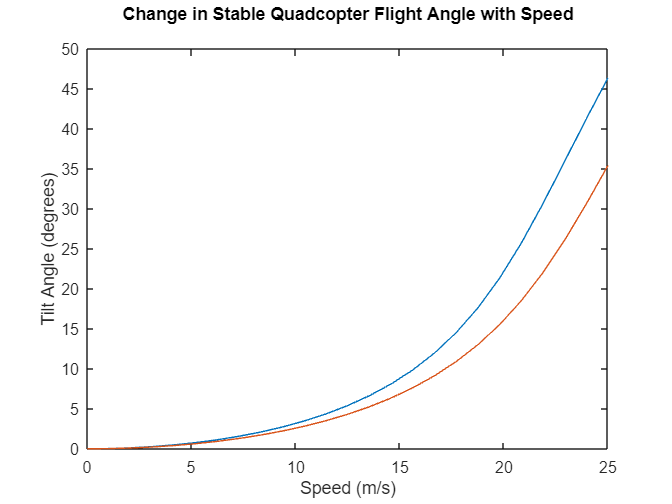

% calculates and plots the change in flight angle with speed
speeds = linspace(0,25,25);
saData = arrayfun(@(sp) flightAngle(sp,Cd,Cl,p,At,Af,m1,g),speeds);
saData2 = arrayfun(@(sp) flightAngle(sp,Cd,Cl,p,At,Af,m2,g),speeds);
plot(speeds,saData);
hold on
plot(speeds,saData2);
xlabel('Speed (m/s)');
ylabel('Tilt Angle (degrees)');
title('Change in Stable Quadcopter Flight Angle with Speed',' ')
hold off

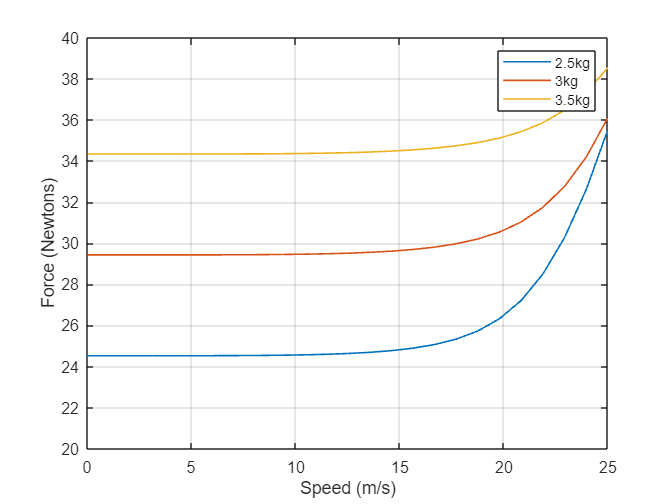

% calculates and plots the change in drag force with speed
[dragData, thrustData]= arrayfun(@(sp) force(sp,Cd,Cl,p,At,Af,m1,g),speeds);
[dragData2, thrustData2]= arrayfun(@(sp) force(sp,Cd,Cl,p,At,Af,m2,g),speeds);
[dragData3, thrustData3]= arrayfun(@(sp) force(sp,Cd,Cl,p,At,Af,m3,g),speeds);

plot(speeds, thrustData, 'linewidth',1);
hold on
plot(speeds, thrustData2, 'linewidth',1);
hold on
plot(speeds, thrustData3, 'linewidth',1);
legend('2.5kg','3kg', '3.5kg', 'FontName','Arial')
xlabel('Speed (m/s)', 'FontName','Arial');
ylabel('Force (Newtons)', 'FontName','Arial');
ylim([20 40]);
grid on

function fAng = flightAngle(s,Cd,Cl,p,At,Af,m,g)
    syms ang
    D = (0.5*(Cd)*p*(At*sind(ang)+Af*cosd(ang))*s^2);
    fAng = vpasolve(ang-atand(D/((m*g)-Cl*D)), ang); % solves numerically
end

function tiltA = tiltArea(top, front, angle)
    tiltA = top*sind(angle) + front*cosd(angle);
end

function [drag, thrust] = force(s,Cd,Cl,p,At,Af,m,g)
    tiltAngle = flightAngle(s,Cd,Cl,p,At,Af,m,g);
    Ad = tiltArea(At, Af, tiltAngle);
    drag = ((Cd*(1+tiltAngle/90))*p*Ad*s^2)/2;
    thrust = (m*g)/cosd(tiltAngle);
end

function power =pCons(s,d,mm,mc,Cd,Cl,p,At,Af,m,g)
    [~, thrust] = force(s,Cd,Cl,p,At,Af,m,g);
    cons = (((thrust/g)*1000/4)*mm+mc)*4;
    t = d/s;
    power = cons*t/3600;
end





